# **Marginal Analyses:** *A Guide*

The code in this live-script references functions contained in `analyze.marg.`

Many of the population-level analyses that are described in assessments of neurophysiological spiking population dynamics seek to interpret not necessarily the mean firing rate, which indeed co-varies most strongly with specific elements of behavior, but rather, the unaccounted **variance **in underlying processes (sometimes referred to as *factors*), which might otherwise be better explained when viewed in covariance of overall population "dispersion" under certain task-specific conditions. This script tries to walk through that process in a sensible way.

### Initialize `marg` Data

#### `Clear workspace & load data (if needed)`

clearvars -except T
if exist('T','var')==0
   % note that `'rate_table_default_matfile'` is the smaller table
   % it does not necessarily contain all Alignments etc. (just to save time
   % on loading). It may be necessary to load the other, larger `'T.mat'`
   % file, which doesn't have _default.mat apprended on the end of the
   % filename.
   load(defaults.files('rate_table_default_matfile'),'T');
end

#### Reduce table to working subset, `M`

M = analyze.marg.get_subset(T);

# **Remove Relevant Marginalizations**

### Subtract group means in a principled way

We expect there to be large, striking differences in the observed neurophsyiological spiking time-series, with this being unsurprising for the following marginalizations: 

- **Group (Ischemia vs. Intact)**

- **Rat (Random)**

- **Block (Post-Op Day)**

- **Area (Premotor vs. Motor)**

- **ICMS Representation (Forelimb vs. Face, for example)**

- **Channel (a huge difference for individual channels)**

M = analyze.marg.subtract_rat_means(M);

### View example of mean-subtracted rates

Click **Plot Rates **once you have selected the desired *Alignment *and *Outcome *parameters.

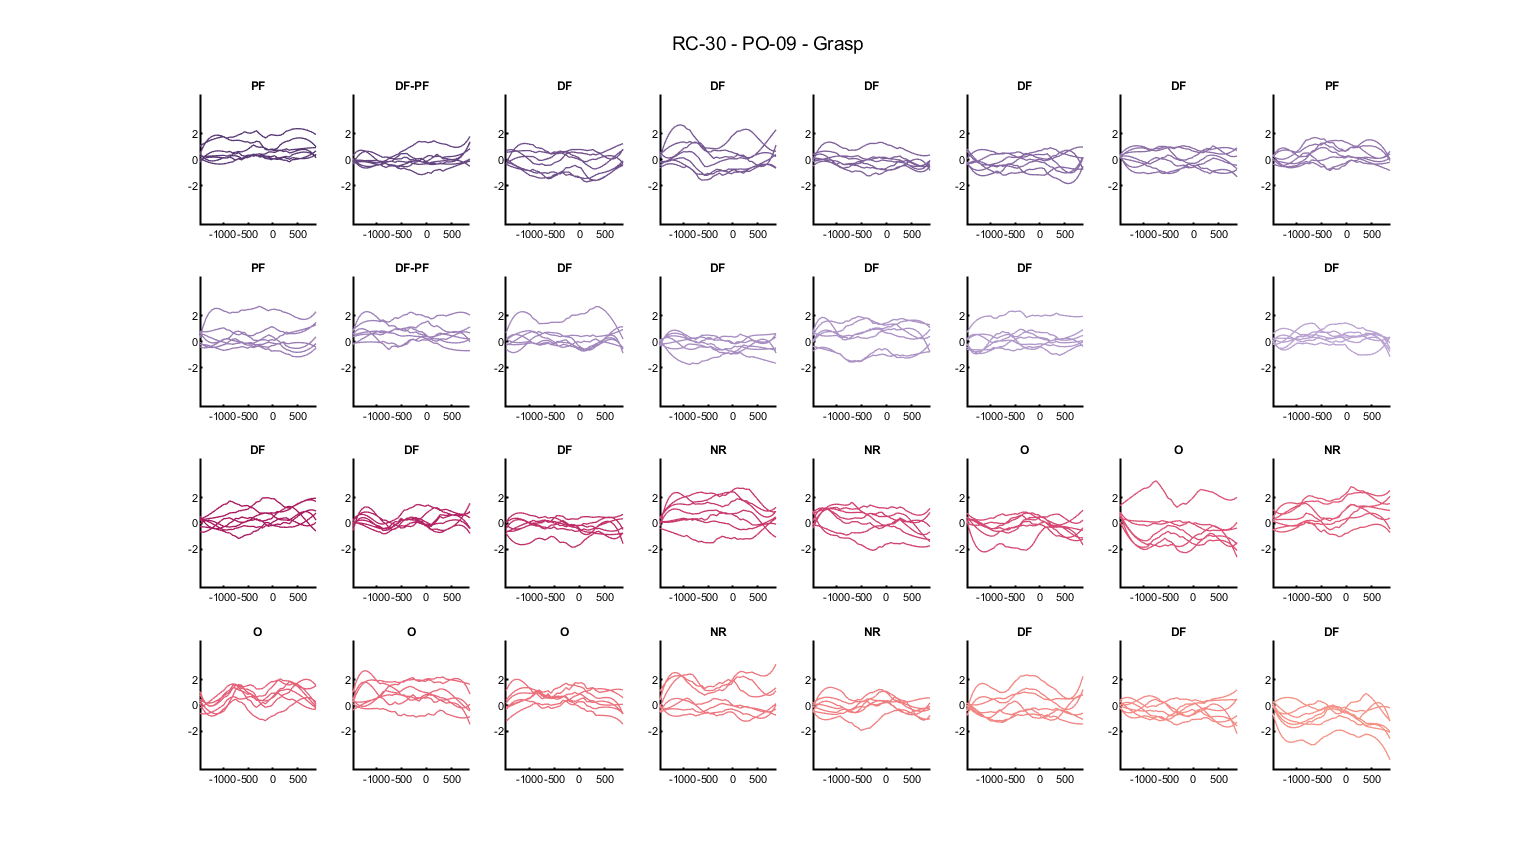

align_event = 'Grasp';
outcome = 'Successful';
min_n_trials = 6;
save_fig = false; % Auto-saves the figure, if ticked
  % This will change `small-m` (table) each time you click it

[fig_by_Channel,m] = analyze.rec.plot_rate(...
    utils.filterByNTrials(M,min_n_trials,outcome),... 
    align_event,outcome,save_fig,1);

This figure produces subplots for **all trials **of a **single Block**. Each subplot represents a different channel. The top two rows represent normalized spike rates on channels that are in Caudal Forelimb Area (CFA; rat M1 homolog) that is ipsilateral to the forelimb retrieving the pellet. The bottom two rows represent normalized spike rates on channels that are in Rostral Forelimb Area (RFA; rat PM homolog) contralateral to the forelimb retrieving the pellet. Time is represented on the x-axis in milliseconds. The bold text above each subplot indicates the approximate intracortical microstimulation (ICMS) co-registration from a mapping procedure done just prior to the insertion of the microwire arrays. It follows the key:

- **Distal Forelimb **(DF)

- **Proximal Forelimb **(PF)

- **Distal & Proximal Forelimb **(DF-PF)

- **No Response **(NR; 80 uA maximum current)

- **Other **(O; e.g. Trunk, Vibrissae, Mouth, etc.)

Verify that the mean-subtracted outcomes make sense; **the largest "modulated" component should be the task-aligned one. **Since we do not typically see "traditionally" coherent task-related fluctuations, particularly around the **0-ms** task alignment, it looks like we correctly subtracted the mean. You can see if there is a difference by toggling the check-box below.

if false
    [fig_by_Channel_orig] = analyze.rec.plot_rate(T(ismember(T.RowID,m.RowID),:),...
        align_event,outcome,save_fig,1); %#ok<UNRCH> 
end

# **Apply Population-Level Analysis**

Using our marginalized dataset, we can now apply population-level analysis. A principled approach is detailed in (cite), which describes **jPCA, **a method that attempts to assess the strength of *rotatory dynamics *present under the assumption that the population dynamics are the result of factors governed in an oscillatory fashion, which is captured by a system of differential equations as:


$$\delta X=XM_{\mathrm{skew}}$$


Where $M_{\mathrm{skew}}$ is constrained to be skew-symmetric during the optimization procedure (a least-squares minimization). The recovered fit should then be compared to $M_{\mathrm{best}}$, which is the optimal solution in the least-squares sense. If the fits are *comparable *(and that part can be nebulous; in general, it would seem that you want the top pairs of eigenvectors to capture 20-40% of the observed data variance as a seeming rule of thumb).

## Organize data for `jPCA` code

*Note that all code in *`analyze.jPCA`* is based on code kindly provided by John P. Cunningham & Mark Churchland; it has been changed slightly from the original format to accomodate some optional parameters for visualization purposes, and the documentation is changed to reflect notes as I was learning the material.*

% We will use the (small-m) matrix that we inspected rates for above.
[Data,J,JID] = analyze.jPCA.convert_table(m,...
    'Alignment',align_event,...
    'Outcome',outcome);